## plot one channel's spectrum

chann_num = 1

chann_num = 1

sample_from_batch_num = 1

sample_from_batch_num = 1

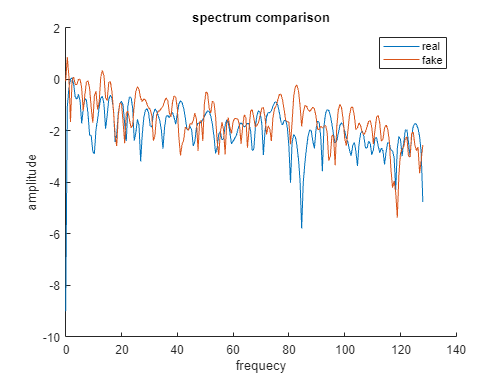

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
spectrum_real = spectral_real(sample_from_batch_num, chann_num, :);
spectrum_fake = spectral_fake(sample_from_batch_num, chann_num, :);
spectrum_real = spectrum_real(:);
spectrum_fake = spectrum_fake(:);
hold on 
plot(freqs, spectrum_real, 'DisplayName', 'real')
plot(freqs, spectrum_fake, 'DisplayName', 'fake')
hold off

title('spectrum comparison')
xlabel('frequecy')
ylabel('amplitude')
legend

## plot all channels spectrum

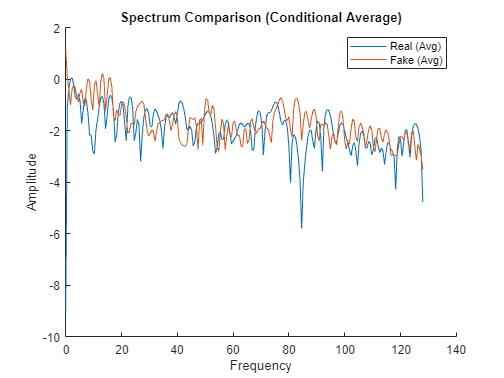

sample_from_batch_num = 1;

% Define the condition for averaging (replace with your specific condition)
average_condition = true;  % Example condition, replace with your logic

if average_condition
  % Calculate average spectrum across channels
  spectrum_real = mean(squeeze(spectral_real(sample_from_batch_num, :, :)), 1);
  spectrum_fake = mean(squeeze(spectral_fake(sample_from_batch_num, :, :)), 1);
else
  spectrum_real = squeeze(spectral_real(sample_from_batch_num, :, :)); 
  spectrum_fake = squeeze(spectral_fake(sample_from_batch_num, :, :));
end

% Plotting
hold_on = true;  % Adjust based on your preference

figure;  % Create a new figure window

if hold_on
  hold on;  % Enable hold for plotting on the same figure
end

plot(freqs, spectrum_real, 'DisplayName', 'Real (Avg)');
plot(freqs, spectrum_fake, 'DisplayName', 'Fake (Avg)');

if hold_on
  hold off;  % Disable hold if using hold_on
end

title('Spectrum Comparison (Conditional Average)');
xlabel('Frequency');
ylabel('Amplitude');
legend;

## plot one channel's raw samples

chann_num = 1

chann_num = 1

sample_from_batch_num = 1

sample_from_batch_num = 1

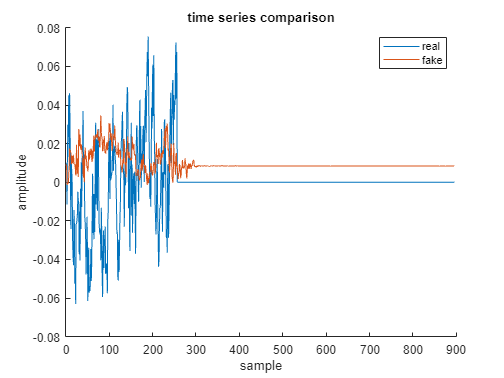

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
signal_real = squeeze(X_real(sample_from_batch_num, chann_num, :));
signal_fake = squeeze(X_fake(sample_from_batch_num, chann_num, :));
hold on 
plot(signal_real, 'DisplayName', 'real')
plot(signal_fake, 'DisplayName', 'fake')
hold off

title('time series comparison')
xlabel('sample')
ylabel('amplitude')
legend

## plot all channels raw samples

sample_from_batch_num = 1

sample_from_batch_num = 1

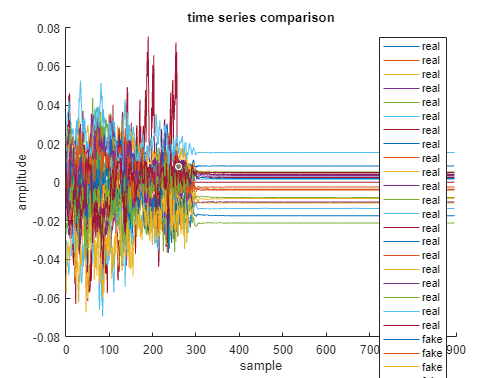

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
signal_real = squeeze(X_real(sample_from_batch_num, :, :))';
signal_fake = squeeze(X_fake(sample_from_batch_num, :, :))';
hold on 
plot(signal_real, 'DisplayName', 'real')
plot(signal_fake, 'DisplayName', 'fake')
hold off

title('time series comparison')
xlabel('sample')
ylabel('amplitude')
legend